for table_i=1:50
    n{table_i} = ['Hidden Layer size: ' num2str(table_i,'%d')];
end
name=n';
table_2_lm=array2table([rms_val_lm,r2_val_lm,mape_val_lm T_lm],"VariableNames",{'ΔP/ΔPo(rmse)','ΔNu/ΔNuo(rmse)','ΔP/ΔPo(R2)','ΔNu/ΔNuo(R2)','ΔP/ΔPo(mape)','ΔNu/ΔNuo(mape)','Elapsed Time'});
table_2_lm=cat(2,name,table_2_lm)

table_2_lm = 50×8 table
              Var1               ΔP/ΔPo(rmse)    ΔNu/ΔNuo(rmse)    ΔP/ΔPo(R2)    ΔNu/ΔNuo(R2)    ΔP/ΔPo(mape)    ΔNu/ΔNuo(mape)    Elapsed Time
    _________________________    ____________    ______________    __________    ____________    ____________    ______________    ____________

    {'Hidden Layer size: 1' }       0.34298          0.11457        0.083908       0.49319          14.832           9.6749           1.6503   
    {'Hidden Layer size: 2' }       0.16476          0.11754          0.7886        0.4665          9.1842           9.8874           1.2715   
    {'Hidden Layer size: 3' }       0.11464          0.10756         0.89765       0.55327          7.0106           8.7044    


table_2_bay=array2table([rms_val_bay,r2_val_bay,mape_val_bay T_bay],"VariableNames",{'ΔP/ΔPo(rmse)','ΔNu/ΔNuo(rmse)','ΔP/ΔPo(R2)','ΔNu/ΔNuo(R2)','ΔP/ΔPo(mape)','ΔNu/ΔNuo(mape)','Elapsed Time'});
table_2_bay=cat(2,name,table_2_bay)

table_2_bay = 50×8 table
              Var1               ΔP/ΔPo(rmse)    ΔNu/ΔNuo(rmse)    ΔP/ΔPo(R2)    ΔNu/ΔNuo(R2)    ΔP/ΔPo(mape)    ΔNu/ΔNuo(mape)    Elapsed Time
    _________________________    ____________    ______________    __________    ____________    ____________    ______________    ____________

    {'Hidden Layer size: 1' }       0.34105          0.11597        0.094169       0.48069          14.754           9.8429            2.008   
    {'Hidden Layer size: 2' }       0.16485           0.1176         0.78837       0.46595          9.2052           9.9035           1.2957   
    {'Hidden Layer size: 3' }       0.11506          0.10748         0.89691       0.55396          7.0316           8.6898   


table_2_scg=array2table([rms_val_scg,r2_val_scg,mape_val_scg T_scg],"VariableNames",{'ΔP/ΔPo(rmse)','ΔNu/ΔNuo(rmse)','ΔP/ΔPo(R2)','ΔNu/ΔNuo(R2)','ΔP/ΔPo(mape)','ΔNu/ΔNuo(mape)','Elapsed Time'});
table_2_scg=cat(2,name,table_2_scg)

table_2_scg = 50×8 table
              Var1               ΔP/ΔPo(rmse)    ΔNu/ΔNuo(rmse)    ΔP/ΔPo(R2)    ΔNu/ΔNuo(R2)    ΔP/ΔPo(mape)    ΔNu/ΔNuo(mape)    Elapsed Time
    _________________________    ____________    ______________    __________    ____________    ____________    ______________    ____________

    {'Hidden Layer size: 1' }       0.24083          0.15756        0.54833        0.041492         11.171           14.498           2.0325   
    {'Hidden Layer size: 2' }       0.16674           0.1177         0.7835         0.46512         9.3144           9.9042           1.1449   
    {'Hidden Layer size: 3' }       0.11592          0.10812        0.89535         0.54861         6.8773            8.794   


writetable(table_2_lm,'D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/Performence(validation).xlsx','Sheet','Lavenberg')
writetable(table_2_bay,'D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/Performence(validation).xlsx','Sheet','bayesian')
writetable(table_2_scg,'D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/Performence(validation).xlsx','Sheet','Scg')

**Which algorithm is better among all**

all=[table_2_lm;table_2_bay;table_2_scg];
all_r2=all(:,4:5);
all_r2_array=table2array(all_r2);
all_r2_array_sum=sum(table2array(all_r2(:,1:2)),2)

all_r2_array_sum =     0.5771
    1.2551
    1.4509
    1.5187
    1.6656
    1.7670
    1.7082
    1.7828
    1.8100
    1.8238


[junk, index] = max(all_r2_array_sum(:,1));
r2_p=all_r2_array(index,1);
r2_nu=all_r2_array(index,2);
if index<=50
    X=['Best Alg=Lavenberg Marquardt\nbest hidden layer no: ',num2str(index),'\nr2 value for pressure ',num2str(r2_p),'\nr2 value for Nu ',num2str(r2_nu)];
elseif index>50 && index<=100
    X=['Best Alg=Bayesian\nbest hidden layer no: ',num2str(index-50),'\nr2 value for pressure ',num2str(r2_p),'\nr2 value for Nu ',num2str(r2_nu)];
else
    X=['Best Alg=Scaled Conjugate Gradient\nbest hidden layer no: ',num2str(index-100),'\nr2 value for pressure ',num2str(r2_p),'\nr2 value for Nu ',num2str(r2_nu)];
end
fprintf(X)

Best Alg=Bayesian
best hidden layer no: 48
r2 value for pressure 0.99672
r2 value for Nu 0.98754

**Best hidden layer number for Lavenberg**

lm_r2_array=table2array(table_2_lm(:,2:7));
lm_r2_array_sum=sum(lm_r2_array(:,3:4),2);
[junk, index] = max(lm_r2_array_sum(:,1));
r2_p=lm_r2_array(index,3);
r2_nu=lm_r2_array(index,4);
rmse_p=lm_r2_array(index,1);
rmse_nu=lm_r2_array(index,2);
mape_p=lm_r2_array(index,5);
mape_nu=lm_r2_array(index,6);
X=['\nFor Lavenberg Marquardt\nbest hidden layer no: ',num2str(index),'\nr2 value for pressure ',num2str(r2_p),'\nr2 value for Nu ',num2str(r2_nu) ... 
    ,'\nrmse value for pressure ',num2str(rmse_p),'\nrmse value for Nu ',num2str(rmse_nu) ...
    ,'\nmape value for pressure ',num2str(mape_p),'\nmape value for Nu ',num2str(mape_nu)];
fprintf(X)


For Lavenberg Marquardt
best hidden layer no: 45
r2 value for pressure 0.99587
r2 value for Nu 0.9877
rmse value for pressure 0.023041
rmse value for Nu 0.017847
mape value for pressure 1.3525
mape value for Nu 1.4263

**Best hidden layer number for Bayesian**

bay_r2_array=table2array(table_2_bay(:,2:7));
bay_r2_array_sum=sum(bay_r2_array(:,3:4),2);
[junk, index] = max(bay_r2_array_sum(:,1));
r2_p=bay_r2_array(index,3);
r2_nu=bay_r2_array(index,4);
rmse_p=bay_r2_array(index,1);
rmse_nu=bay_r2_array(index,2);
mape_p=bay_r2_array(index,5);
mape_nu=bay_r2_array(index,6);
X=['For Bayesian\nbest hidden layer no: ',num2str(index),'\nr2 value for pressure ',num2str(r2_p),'\nr2 value for Nu ',num2str(r2_nu) ... 
    ,'\nrmse value for pressure ',num2str(rmse_p),'\nrmse value for Nu ',num2str(rmse_nu) ...
    ,'\nmape value for pressure ',num2str(mape_p),'\nmape value for Nu ',num2str(mape_nu)];
fprintf(X)

For Bayesian
best hidden layer no: 48
r2 value for pressure 0.99672
r2 value for Nu 0.98754
rmse value for pressure 0.020511
rmse value for Nu 0.01796
mape value for pressure 1.2023
mape value for Nu 1.405

**Best hidden layer number for SCG**

scg_r2_array=table2array(table_2_scg(:,2:7));
scg_r2_array_sum=sum(scg_r2_array(:,3:4),2);
[junk, index] = max(scg_r2_array_sum(:,1));
r2_p=scg_r2_array(index,3);
r2_nu=scg_r2_array(index,4);
rmse_p=scg_r2_array(index,1);
rmse_nu=scg_r2_array(index,2);
mape_p=scg_r2_array(index,5);
mape_nu=scg_r2_array(index,6);
X=['For SCG\nbest hidden layer no: ',num2str(index),'\nr2 value for pressure ',num2str(r2_p),'\nr2 value for Nu ',num2str(r2_nu) ...
    ,'\nrmse value for pressure ',num2str(rmse_p),'\nrmse value for Nu ',num2str(rmse_nu) ...
    ,'\nmape value for pressure ',num2str(mape_p),'\nmape value for Nu ',num2str(mape_nu)];
fprintf(X)

For SCG
best hidden layer no: 50
r2 value for pressure 0.98958
r2 value for Nu 0.9652
rmse value for pressure 0.036575
rmse value for Nu 0.030021
mape value for pressure 2.1844
mape value for Nu 2.4763

[T_lm_val;T_bay_val;T_scg_val]

ans = 6×6 table
           Var1             mae          mse          rmse        Rsq       mape 
    __________________    ________    __________    ________    _______    ______

    {'Pressure_ratio'}    0.016183    0.00051939     0.02279    0.99596    1.3579
    {'Nusselt ratio' }    0.013427    0.00038419    0.019601    0.98517    1.5822
    {'Pressure_ratio'}    0.015284     0.0004397    0.020969    0.99658    1.2742
    {'Nusselt ratio' }    0.012057    0.00031772    0.017825    0.98773    1.4049
    {'Pressure_ratio'}    0.049091     0.0045226    0.067251    0.96478    4.1395
    {'Nusselt ratio' }    0.033777     0.0021676    0.046558     0.9163     4.004


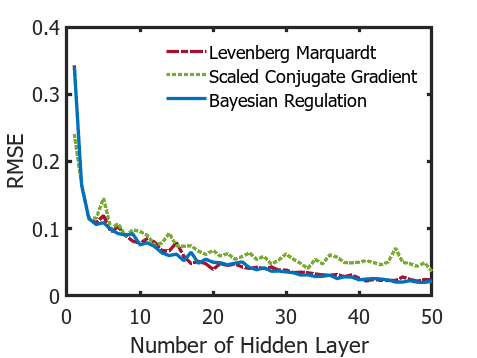

colorstring=[0.6350 0.0780 0.1840; 0.4660 0.6740 0.1880 ; 0 0.4470 0.7410 ; 0.8500 0.3250 0.0980  ];
a=figure();
box on;
hold on;
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times','LineWidth',2.5,'DefaultLineLineWidth',2.5,'ColorOrder',colorstring)
plot(1:50,rms_val_lm(:,1),'LineStyle','-.');
plot(1:50,rms_val_scg(:,1),'LineStyle',':');
plot(1:50,rms_val_bay(:,1));
xlabel('Number of Hidden Layer')
ylabel('RMSE')
% title('ΔP/ΔPo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian Regulation',"Box","off");hold off;
Plot_rmse=sprintf('D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/ΔP÷ΔPo_optimisation(rmse).jpg');
exportgraphics(gcf,Plot_rmse)

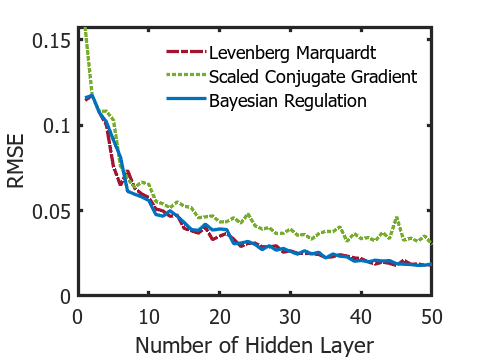


b=figure();
box on;
hold on;
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times','LineWidth',2.5,'DefaultLineLineWidth',2.5,'ColorOrder',colorstring)
plot(1:50,rms_val_lm(:,2),"LineStyle","-.");
plot(1:50,rms_val_scg(:,2),"LineStyle",":");
plot(1:50,rms_val_bay(:,2));
xlabel('Number of Hidden Layer')
ylabel('RMSE')
% title('ΔNu/ΔNuo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian Regulation',"Box","off");hold off;
Plot_rmse=sprintf('D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/ΔNu÷ΔNuo_optimisation(rmse).jpg');
exportgraphics(gcf,Plot_rmse)

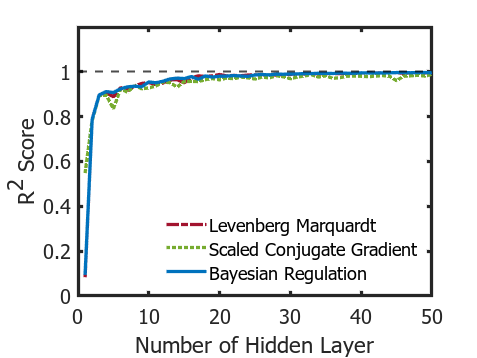

a=figure();
box on;
hold on;
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times','LineWidth',2.5,'DefaultLineLineWidth',2.5,'ColorOrder',colorstring)
plot(1:50,r2_val_lm(:,1),'LineStyle','-.');
plot(1:50,r2_val_scg(:,1),'LineStyle',':');
plot(1:50,r2_val_bay(:,1));
yline(1,'LineWidth',1.5,'LineStyle','--','Color',[0 0 0])
xlabel('Number of Hidden Layer')
ylabel('R^2 Score')
ylim([0 1.2])
% title('ΔP/ΔPo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian Regulation','location','southeast',"Box","off");hold off;
Plot_r2=sprintf('D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/ΔP÷ΔPo_optimisation(r2).jpg');
exportgraphics(gcf,Plot_r2)

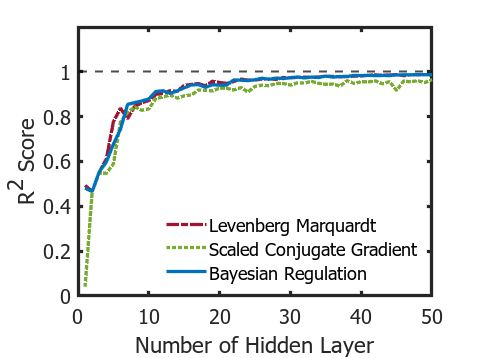


b=figure();
box on;
hold on;
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times','LineWidth',2.5,'DefaultLineLineWidth',2.5,'ColorOrder',colorstring)
plot(1:50,r2_val_lm(:,2),"LineStyle",'-.');
plot(1:50,r2_val_scg(:,2),'LineStyle',':');
plot(1:50,r2_val_bay(:,2));
yline(1,'LineWidth',1.5,'LineStyle','--','Color',[0 0 0])
xlabel('Number of Hidden Layer')
ylabel('R^2 Score')
ylim([0 1.2])
% title('ΔNu/ΔNuo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian Regulation','location','southeast',"Box","off");hold off;
Plot_r2=sprintf('D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/ΔNu÷ΔNuo_optimisation(r2).jpg');
exportgraphics(gcf,Plot_r2)

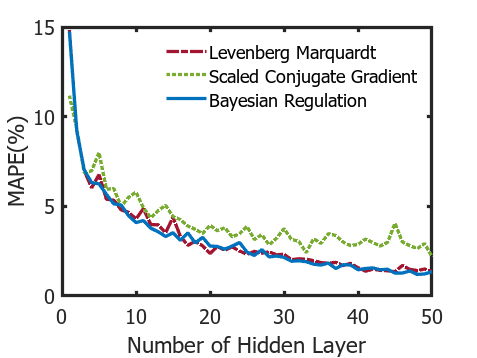

a=figure();
box on;
hold on;

set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times','LineWidth',2.5,'DefaultLineLineWidth',2.5,'ColorOrder',colorstring)
plot(1:50,mape_val_lm(:,1),"LineStyle","-.");
plot(1:50,mape_val_scg(:,1),"LineStyle",":");
plot(1:50,mape_val_bay(:,1));
xlabel('Number of Hidden Layer')
ylabel('MAPE(%)')
% title('ΔP/ΔPo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian Regulation',"Box","off");hold off;
Plot_mape=sprintf('D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/ΔP÷ΔPo_optimisation(mape).jpg');
exportgraphics(gcf,Plot_mape)

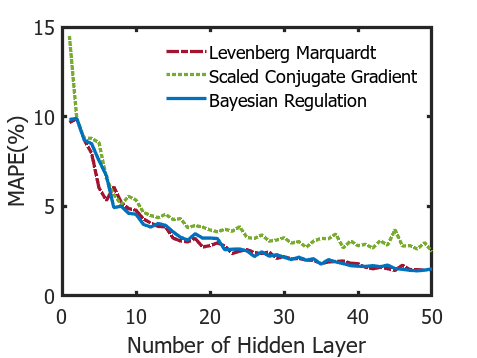


b=figure();
box on;
hold on;

set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times','LineWidth',2.5,'DefaultLineLineWidth',2.5,'ColorOrder',colorstring)
plot(1:50,mape_val_lm(:,2),"LineStyle","-.");
plot(1:50,mape_val_scg(:,2),"LineStyle",":");
plot(1:50,mape_val_bay(:,2));
xlabel('Number of Hidden Layer')
ylabel('MAPE(%)')
% title('ΔNu/ΔNuo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian Regulation',"Box","off");hold off;
Plot_mape=sprintf('D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/ΔNu÷ΔNuo_optimisation(mape).jpg');
exportgraphics(gcf,Plot_mape)

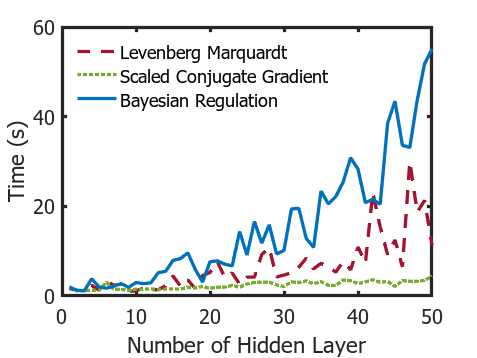

a=figure();
box on;
hold on;

set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times','LineWidth',2.5,'DefaultLineLineWidth',2.5,'ColorOrder',colorstring)
plot(1:50,table2array(table_2_lm(:,8)),"LineStyle","--");
plot(1:50,table2array(table_2_scg(:,8)),"LineStyle",":");
plot(1:50,table2array(table_2_bay(:,8)));
xlabel('Number of Hidden Layer')
ylabel('Time (s)')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian Regulation',"Box","off",'location','northwest');hold off;
Plot_time=sprintf('D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/Time.jpg');
exportgraphics(gcf,Plot_time)